# **Digital Communications TTT4130 - Matlab Lab Sessions**

**Lab Responsible**: Johan Suarez (johan.suarez@ntnu.no)

`Prerequisites`

Up-to-date installation of `MATLAB `and `SIMULINK `including `Communications Toolbox. (NTNU students receive Campus license)`

`Instructions`

**All lab sessions are group projects. Groups will be assigned randomly and consist of 2-3 people.** 

This is a Matlab live script. The script will guide through the lab session with coding tasks accompanied by explanations and comments. The live script and the project report must be completed and delivered by **18.10.2024**

**Please download and install MATLAB/Simulink and include the Communications toolbox as add-in. **

**You are free to use any resource you think is useful. Collaboration and discussion between groups is encouraged. **

# `Project 2`

This lab session covers mainly *synchronisation *in digital communication systems.

### `Digital Communiction System Schematic`

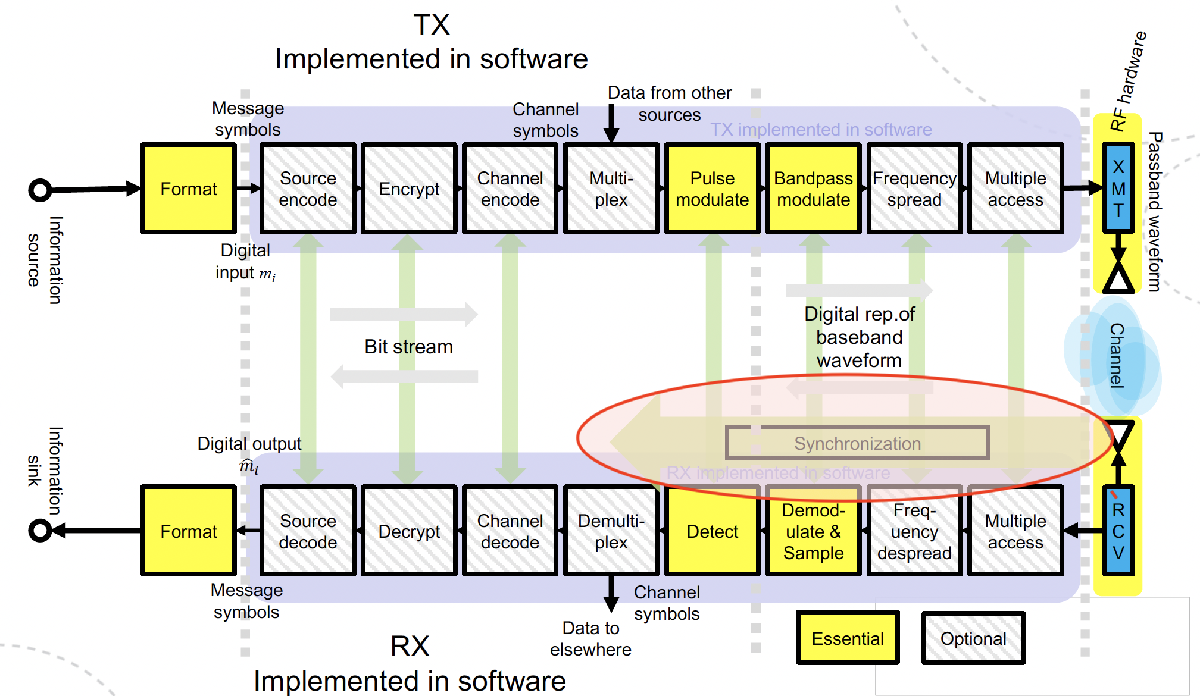

Specifically, the lab session covers the highlighted (red) parts of the schematic depicted above. 

`Course Content`

- Synchronisation in digital communication systems

- Why synchronisation is needed ... 

- Channel and hardware effects 

#### `System Configuration (known from Project 1)`

% Symbol Rate 
symRate = 1000;         % 1/s


SNR = Simulink.Parameter(30)       % Signal to Noise ratio, specifically Energy per bit to Noise Power density ratio (Eb/No)

SNR =   Parameter with properties:

          Value: 30
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


Select modulation scheme

modScheme = "BPSK"

modScheme = "BPSK"



% For M-ary QAM specify modulation order (TODO: assert modOrder == 2/4 for modScheme == BPSK/QPSK)

modOrder = 2

modOrder = 2

Specify Transmit Filter Parameters

alpha =0.35  % Nyquist Filter Roll-Off Factor

alpha = 0.3500



filterLenSymbols = 10;            % Filter Length in Symbols


samplesPerSymbol = 8;             % Filter Upsampling Factor


################################# NEW  ##################################

% Specify the "virtual" carrier frequency 

fCRes = Simulink.Parameter(0);




% Phase Offset
phaseOffsets = Simulink.Parameter([0;pi/8;pi/4;pi/2;pi]);

phaseOffsetSelector  = Simulink.Parameter(1);


% Toggle Synchronisation Processes

toggleFLL = Simulink.Parameter(1); 

toggleTimingRecovery = Simulink.Parameter(1); 

togglePLL = Simulink.Parameter(1); 



`Task1 : Channel Effects`

**TODO: Provide more detail regarding the phase and frequency impairment model. **

Investigate which effects a phase offset ($\Delta \phi_{\textrm{LO}}$) and a frequency offset ($\Delta f_{LO}$ ) between the Tx and Rx local oscillator (LO) have on the received signal. Use the signal model for an analytic signal upconverted to passband

##                                 
$$s_+(t) = s(t) e^{j2\pi f_{c,tx}t}$$


which is mixed to baseband by a receiver LO with frequency $f_{c,Rx}=f_{c,Tx}+\Delta f$ and relative phase offset $\Delta \phi_{\textrm{LO}}$. In this task assume that $s(t)$ are downsampled complex symbols.

Considering the frequency and phase offset, then the received signal mixed to baseband can be rewritten as:

## 
$$s_+(t) = s(t) e^{j2\pi ((f_{c,rx}+\Delta f)t+\Delta \phi)} = s(t) e^{j2\pi t f_{c,rx}}e^{j2\pi t \Delta f}e^{j2\pi \Delta \phi}$$


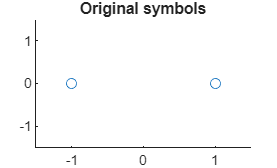

% Investigate LO phase and freqeuncy offset on analytic baseband signal 

% Time of Frame including barker code (barker code is technically only needed for last exercise)
time = (0:1/symRate:1-1/symRate+1/symRate * 13)'; 

% Generate Tx message symbols
Nmsg = 1000;
% QPSK:
%bitsI = randi([0 1], Nmsg, 1);
%bitsQ = randi([0 1], Nmsg, 1);
%symTx_msg = (2*bitsI - 1) + 1j*(2*bitsQ - 1);
%symTx_msg = symTx_msg / sqrt(2);
% BPSK:
bitsI = randi([0 1], Nmsg, 1);

barker_code = [-1 -1 -1 -1 -1 +1 +1 -1 -1 +1 -1 +1 -1];
symTx_msg = 2*bitsI - 1;

symTx = [barker_code';symTx_msg];

% Define a Tx frequency
fc_Tx = 20e3; 

% Plot Tx symbols
figure;
scatter(symTx,zeros(1,length(symTx)))
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
title("Original symbols")

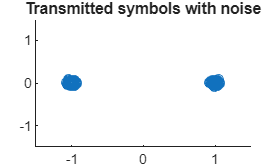


% Generate real and imaginary parts of the noise
Noise_R = randn(length(symTx),1);
Noise_I = randn(length(symTx),1);
% By default, randn considers mean 0 and variance 1 (and of course, power 1)

% Combine them to create complex Gaussian noise
Noise_C = 1/sqrt(2)*(Noise_R + Noise_I*1j);
% Real and Imaginary noise have energy 1, so we divide by sqrt(2) to obtain
% unit energy in the Complex Noise.

% Impair Tx signal with noise
% Since fc_Tx takes values in -1 and 1, its total power is equal to its
% length. Same for Noise_C, since the variance is 1 per each bit:
symTx = symTx + (1/SNR.Value)*Noise_C;


figure;
scatter(real(symTx),imag(symTx))
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
title("Transmitted symbols with noise")

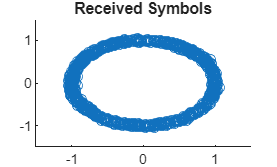


% Upconversion (using padding)
symTx_upconv = zeros(length(symTx)*samplesPerSymbol,1);
for i=0:length(symTx)-1
    symTx_upconv(i*samplesPerSymbol+1) = symTx(i+1);
end
%symTx = symTx_upconv;


% Implement phase and frequency impairments resulting from LO offset
phaseOffsets.Value(phaseOffsetSelector.Value) = pi/4;
fCRes.Value = 61;
Fs = symRate * samplesPerSymbol; % sampling frequency
time2 = (0:length(symTx_upconv)-1)'/Fs;
symRx = exp(1j*2*pi*phaseOffsets.Value(phaseOffsetSelector.Value)) *symTx_upconv .* exp(1j*2*pi*fCRes.Value.*time2);


% Downconvert signal to baseband
sigDC = zeros(length(symTx_upconv)/samplesPerSymbol,1);
for i=0:length(symRx)/samplesPerSymbol-1
    sigDC(i+1) = symRx(i*samplesPerSymbol+1);
end

figure;
scatter(real(sigDC), imag(sigDC))
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
title("Received Symbols");

`Task 2 : Synchronisation Effects`

Synchronisation in (digital) communication systems aims for removing the phase and frequency effects and impairments discussed above. The simulink model contains blocks on the receiver end of the communication link that implement the following crucial synchronisation steps:

- Coarse Frequency Correction with e.g., **Frequency-Locked Loop (FLL) **(Matlab uses corrrelation and FFT based methodss)

- Timing Offset Correction with a **Symbol Synchronizer **

- Residual Frequency Offset Correction and Phase Sychronisation with a **Phase-Locked Loop (FLL) n                                                                                                                                                                                                                                                                                               **

**Toggle the different synchronisation steps and observe the resulting signal characterisitcs (eye diagram, constellation diagram, signal spectrum) in each case. Explain the observations and argue mathematically where you see fit. **

[explain the observations]

`Task 3 : Implementation of a Costas-Loop (data-free synchronization)`

 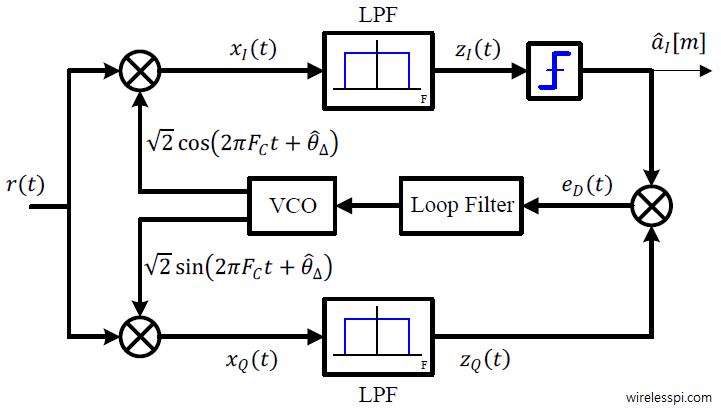

The illustration above shows the principle architecture of a *Costas Loop* for a **BPSK** receiver architecture (**NB! The illustration above treats a passband signal; our system operates on a *****complex baseband  signal***). The Costas loop is a variation of the traditional PLL that uses the IQ demodulation principles to lock onto the phase (and frequency) of a signal. 

The first step in the processing chain is the generation of the error signal $e_D$ which measures the phase difference between the reference sinusoid and the input signal. 

The *loop filter *is an integral part of the PLL. The design of the loop filter largely determines the performance characteristics of the PLL. The loop filter follows the basic structure

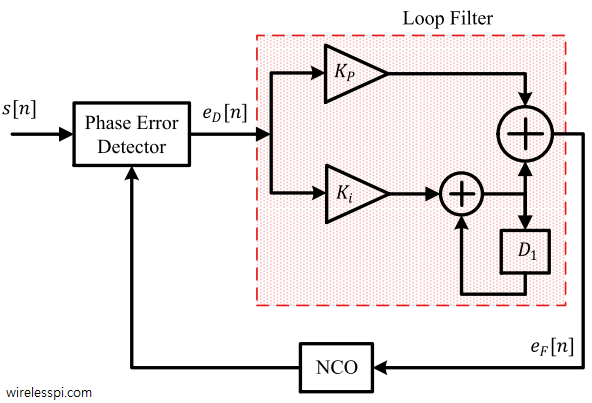

with appropriate filter coefficients $K_p
$ and $K_i$. (The *D1 *block is a one-step time-delay)

The generated and loop filtered *error signal *$e_F$ serves as input to a *Numerically Controlled Cscillator* (NCO).The NCO adjusts the phase of the generated sinusoid as

                                                             
$$\phi_{NCO}\leftarrow\phi_{NCO}+K_0e_F$$


where $K_0$ is the gain of the NCO. This essentially constitutes an integration or accumulation. 

Imlement the Costas Loop and enable your function in the simulink dashboard. Test the Costas Loop implementation first with the test signal you generated in *Task 1*. You can use the loop parameters defined in the function body. You are welcome to experiment with different parameter values; the loop parameter largely determine the the Costas loop performance, so it is interesting to observe how changes in parameters impact the outcome. 

**NB! Make sure that *****modScheme = "BPSK" *****when testing the function in the Simulink model. **

%costasLoop(...);  %

% Run the Simulink model  
% out = sim("CommSysSimulink_Project2.slx",'StopTime','inf');

% Implementation of Costas Loop
% Implementation is done in the complex regime
function symOut = costasLoop(symIn)

sigDC_costas =   -0.1968 + 0.9352i  -0.5789 + 0.8368i  -0.8945 + 0.4672i  -0.9882 + 0.0419i  -0.9111 - 0.3892i   0.8241 + 0.6231i   0.6594 + 0.7496i  -0.6111 - 0.7436i  -0.7319 - 0.7120i   0.8031 + 0.5992i  -0.9121 - 0.3909i   0.9601 + 0.1923i  -0.9927 + 0.1116i  -0.9448 + 0.3462i  -0.8776 + 0.4356i   0.8990 - 0.4675i  -0.8478 + 0.4425i   0.9602 - 0.3555i   0.9739 - 0.2377i   0.9521 - 0.0740i  -1.0005 - 0.0825i   0.9739 + 0.1262i  -0.9131 - 0.2404i   0.9797 + 0.2125i   0.9732 + 0.2668i   0.9854 + 0.2199i  -0.9953 - 0.1214i   0.9571 + 0.0127i   1.0496 - 0.0052i  -0.9835 + 0.1329i  -1.0102 + 0.1329i   0.9854 - 0.1364i  -0.9586 + 0.0862i   1.0019 - 0.0616i  -0.9945 + 0.0508i  -1.0075 + 0.0395i   0.9643 - 0.0006i  -1.0171 - 0.0210i  -1.0164 - 0.0910i   0.9995 + 0.0683i  -0.9909 - 0.1076i   0.9932 + 0.0737i   1.0172 + 0.0137i  -1.0082 - 0.0021i  -0.9943 + 0.0195i   0.9773 - 0.0701i   0.9750 - 0.0621i   0.9922 - 0.0408i  -0.9788 + 0.0778i  -0.9954 - 0.0100i


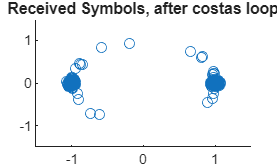

    
    symOut = zeros(1,length(symIn));

    % Loop Filter
    Kp = 0.1;
    Ki = 0.1;
    e1 = 0;
    e2 = 0;

    integrator = 0;
    NCO_phase = 0;

    % NCO Gain
    Ko = 1.5;

    % Implement Costas Loop
    for i = 1:length(symIn)

        % signal generated by VCO
        symOut(i) = symIn(i) * exp(-1j*NCO_phase);

        % Phase difference, update e1
        e1 = imag(symOut(i)) * sign(real(symOut(i)));

        % Loop filter
        integrator = integrator + Ki*e1;
        e2 = Kp*e1+integrator;

        % symOut is the output of the NCO
        NCO_phase = NCO_phase + Ko*e2;

    end

end

% Costas Loop Test using impaired signal from the first excercise

sigDC_costas = costasLoop(sigDC)

% Plot received symbols

figure;
scatter(real(sigDC_costas), imag(sigDC_costas))
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
title("Received Symbols, after costas loop");


`Task 4 : Data-aided synchronization`

We can make use of the *known *frame synchronisation sequence (preamble) to estimate the phase and frequency offset in the received symbols. Implement a function that estimates $\Delta\phi_{LO} $ and $\Delta f_{LO}$ from the recieved input signal. Use the estimated values to synchronize the received symbols. 

**NB! If you want to try integrating data-aided synchronisation into the Simulink model, note that the known Barker code preamble has an offset of ****10 samples ****from the start of the input sequence *****symIn*****. For application in the Simulink model, the CFO estimation needs to account for noise in the CFO estimation across frames. For this purpose the following code snippet is included in the function below**

*Can you explain this?*

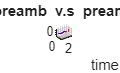

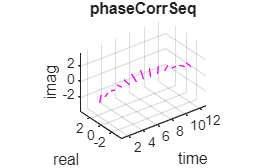

phi0 = -0.9597

freq_offset = -118.3320

% Implement a function that uses the known preamble sequence to estimate
% phase and frequency offset in the received symbol stream
% Tip: Test your function with your simulation data from task 1

% syncedData = dataAidedSync(sigDC)

% Plotting the synchronized data


% out = sim("CommSysSimulink_Project2.slx",'StopTime','inf')
% dataAidedSync(testSym.')

function syncdSymOut = dataAidedSync(symIn)

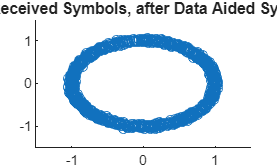


% symIn: preamble sequence + data symbols

% For use in Simulink model 
% persistent cfo_est 
% alpha = 0.7;
% 
%     if isempty(cfo_est)

%         cfo_est = 0;
%     end

preamble = [-1 -1 -1 -1 -1 +1 +1 -1 -1 +1 -1 +1 -1].';

r_preamb = symIn(11:length(preamble)+10);


phaseCorrSeq = r_preamb .* conj(preamble);


phase = angle(phaseCorrSeq);

% You can plot the phase to get an intution 


% Use the functiomn movemean() to lowpass filter the extracted phase
phase = movmean(phase,6);


% Phase offset
phi0 = phase(1);


% Estimate frequency offset


% For Simulink model use: 
% cfo_est = estmP(1)*alpha * (1-alpha)*cfo_est


% Rotate Data to compensate for phase and frequency offset
% NB! For use in the simulink model (again) remember that there is a sample
% offset of 10 samples before the preamble starts (due to application
% specific reasons) 



end

function syncdSymOut = dataAidedSync_matlab(symIn, symRate)

    % symIn: preamble sequence + data symbols
    
    preamble = [-1 -1 -1 -1 -1 +1 +1 -1 -1 +1 -1 +1 -1].';
    
    r_preamb = symIn(1:length(preamble));
    
    phaseCorrSeq = r_preamb .* conj(preamble);
    
    phase = angle(phaseCorrSeq);
    
    % You can plot the phase to get an intution

    figure
    hold on;
    axis equal;
    grid on;
    xlabel('time'); ylabel('real'); zlabel('imag');

    for i = 1:length(r_preamb)
        quiver3(i,0,0,0,real(r_preamb(i)),imag(r_preamb(i)),0,'Color', [0 0 1]);
        quiver3(i,0,0,0,real(preamble(i)),0,'Color', [1 0 0]);
    end
    view(3);
    title("r\_preamb v.s preamble");
    hold off;

    figure
    hold on;
    axis equal;
    grid on;
    xlabel('time'); ylabel('real'); zlabel('imag');

    for i = 1:length(r_preamb)
        quiver3(i,0,0,0,real(phaseCorrSeq(i)),imag(phaseCorrSeq(i)),0,'Color', [1 0 1]);
    end
    view(3);
    title("phaseCorrSeq");
    hold off;


    
    % Use the functiomn movemean() to lowpass filter the extracted phase
    phase = movmean(phase,6);
    
    
    % Phase offset
    phi0 = phase(1)
    
    
    % Estimate frequency offset
    freq_pair_aprox = zeros(length(phase)-1);
    for i=1:(length(phase)-1)
        freq_pair_aprox = (phase(i+1)-phase(i))*symRate;
    end
    freq_par_aprox
    freq_offset = mean(freq_pair_aprox)
    
    
    % Rotate Data to compensate for phase and frequency offset
    time3 = (0:length(symIn)-1)'*1/symRate;
    syncdSymOut = exp(-1j*2*pi*phi0) *symIn .* exp(-1j*2*pi*freq_offset.*time3);
    
    % NB! For use in the simulink model (again) remember that there is a sample
    % offset of 10 samples before the preamble starts (due to application
    % specific reasons) 

end

sigDC_dataaided = dataAidedSync_matlab(sigDC, symRate);

% Plot received symbols

figure
scatter(real(sigDC_dataaided), imag(sigDC_dataaided))
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
title("Received Symbols, after Data Aided Sync");
